clear 
close all


load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data4.mat')
map = Map;
load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map4.mat")
Map = occupancyMap(omap);
network = load("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\DL\mpnet", "mpnet");
mpnet = network.mpnet;

Data

RequiredMaps = 100000

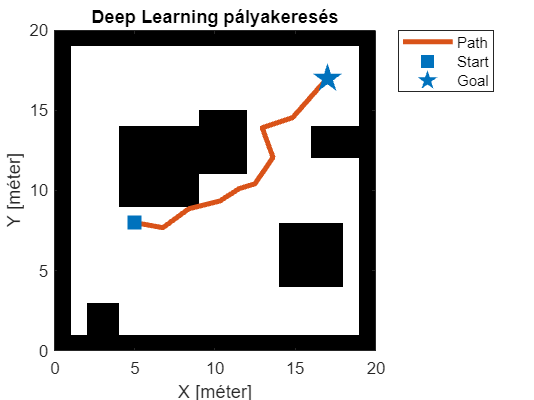

%DL Setup
%We loaded the previously trained deep learning algorithm, and now we are
%going to solve this map
ss = stateSpaceSE2;
ss.StateBounds = [[0 20]; [0 20]; [-3.1416 3.1416]];

stateSamplerDL = stateSamplerMPNET(ss,mpnet);

start = robot_pose;
goal = goal_pose;


stateSamplerDL.Environment = omap;
stateSamplerDL.StartState = start;
stateSamplerDL.GoalState = goal;
stateValidator = validatorOccupancyMap(ss,Map=omap);
stateValidator.ValidationDistance = 0.5;

plannerDLSampling = plannerRRTStar(ss,stateValidator,MaxConnectionDistance=2,StateSampler=stateSamplerDL);
[pathDLSampling,solutionInfoDLSampling] = plan(plannerDLSampling,start,goal);

% Visualize results with deep learning based sampling
figure
show(omap);
hold on;
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:})
%plot(solutionInfoDLSampling.TreeData(:,1),solutionInfoDLSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:})
plot(goal(1),goal(2),plannerLineSpec.goal{:})
legend(Location="northeastoutside")
title("Deep Learning pályakeresés")
xlabel("X [méter]")
ylabel("Y [méter]")


pathDLSampling.States;

%Lidar setup
lidar = rangeSensor;
%VFH setup
vfh = controllerVFH;
vfh.UseLidarScan = true;
vfh.SafetyDistance = 0.2;
%vfh.DistanceLimits = [1 2];

%We show it to see our first part
MapFigure = figure;
VFHFigure = figure;

map(10:12, 14:15) = 1

map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     1     0     0     0  


newMap = flip(map);

newMap(1:end, 1) = 0;
newMap(1, 1:end) = 0;
newMap(1:end, end) = 0;
newMap(end, 1:end) = 0;
newMap

newMap =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     1     1     1     0
     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     1     1     1     0
     0     0     0     

Map = occupancyMap(newMap);

figure(MapFigure);
show(Map)
Map

Map =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [20 20]
             XLocalLimits: [0 20]
             YLocalLimits: [0 20]
             XWorldLimits: [0 20]
             YWorldLimits: [0 20]


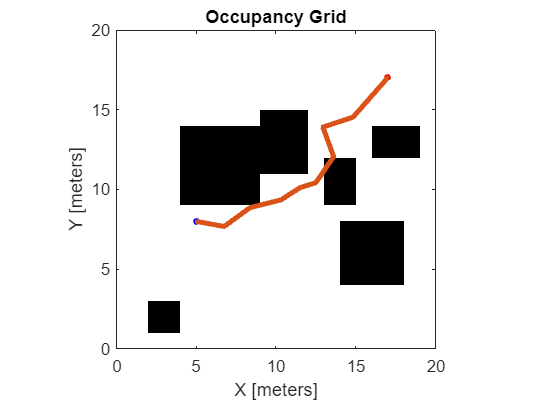

hold on
plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
plot(goal_pose(1), goal_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2, 'Color',"red");
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:});

allVFHdata = [];


wpFollowerObj = uavWaypointFollower("UAVType","multirotor", "StartFrom","first", "Waypoints",pathDLSampling.States);
wpFollowerObj.TransitionRadius = 0.5;

LookAhead = 2;


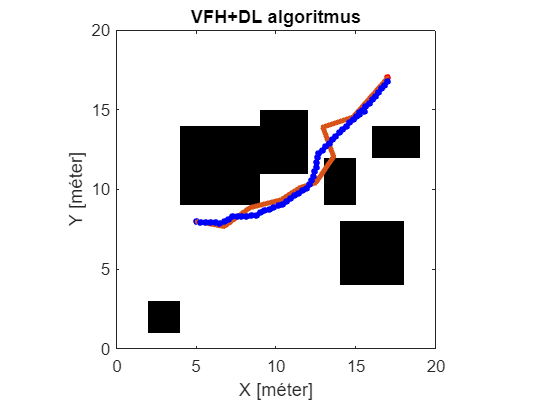

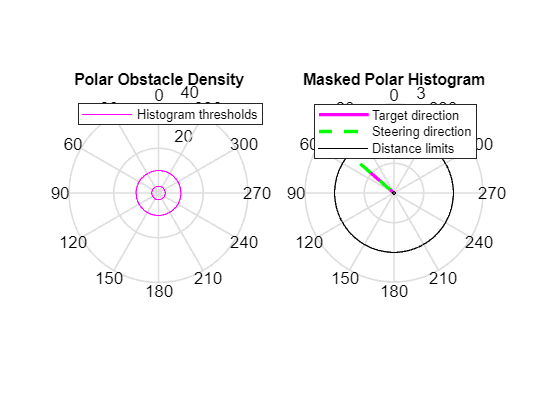

x = 0;
trigger = true;

    while trigger
        %Lidar measures
        [ranges,angles] = lidar(robot_pose,Map);
        
        ranges;

    %Geometry about the angles the be appropriate
    %We calculate the Eucladean distance between the start and end coordinates
        tavolsag_goal_x = goal_pose(1) - robot_pose(1);
        tavolsag_goal_y = goal_pose(2) - robot_pose(2);
    
        Pose = [robot_pose pi/2]';

        [lookaheadPoint,desiredCourse,desiredYaw,lookaheadDistFlag,crossTrackError,status] = wpFollowerObj(Pose, LookAhead);
        Pose;
        lookaheadPoint;

        tavolsag_x = lookaheadPoint(1) - robot_pose(1);
        tavolsag_y = lookaheadPoint(2) - robot_pose(2);
    %We use the atan2d to get back the corresponding angle that is in the four
    %quadrant
        goal_angle = atan2d(tavolsag_y,tavolsag_x);
    %We make a correction with the original orientation of the UAV
        goal_angle= deg2rad(goal_angle)+deg2rad(0-start_orientation);
    %We scan the virtual environment
        scan = lidarScan(ranges,angles);
    %We rotate it to be according to the drone orientation
        rotateScan = transformScan(scan,[0,0,robot_pose(3)+deg2rad(0-start_orientation)]);

    %Use the VFH algorithm to calculate the required steering angle in rad
        steeringDir = vfh(rotateScan,goal_angle);
        steeringDir;
    %Convert it to deg
        new_deg = rad2deg(steeringDir);
        figure(VFHFigure)
        show(vfh)
    %Drone parameter setup
        v_drone = 0.3; %m/s [currently be at 0.2, later we can do dynamic adjustments]

        robot_pose(3) = new_deg;
        robot_pose(1) = robot_pose(1)+cosd(new_deg)*v_drone;
        robot_pose(2) = robot_pose(2)+sind(new_deg)*v_drone;
        allVFHdata = [allVFHdata; robot_pose(1), robot_pose(2)];
        figure(MapFigure);
        plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
        xlabel("X [méter]")
        ylabel("Y [méter]")
        title("VFH+DL algoritmus")
        drawnow
        x = x+1;
    
        if abs(tavolsag_goal_x) < 0.5 && abs(tavolsag_goal_y) < 0.5
            trigger = false;
        end
    end



allVFHdata

allVFHdata =     5.2952    7.9464
    5.5951    7.9525
    5.8924    7.9121
    6.1924    7.9129
    6.4871    7.8568
    6.7648    7.9702
    7.0179    8.1313
    7.2673    8.2981
    7.5671    8.3090
    7.8669    8.3198
